% ASEN 5044 midterm 
% Problem 1

l = 1.85;           % length of rod
m = 2;              % point mass
M = 4;              % cart mass
g = 9.81;           % gravity
dt = 0.05;          % sampling interval
n = 301-1;          % number of samples
tlist = 0:dt:15;    % time sample matrix

A =[ 0,1,0,0;0,0 m*g/M,0; 0,0,0,1;0,0,g*(m+M)/(M*l),0];
B = [0;1/M;0;1/(l*M)];
C = [1,0,-l,0];
D = zeros(1);

Ctilde = zeros(1,4);        % zero matrix to compute DT model
Atilde = [A,B;Ctilde,D];    % compiled matrix
FG=expm(Atilde*dt);         % DT conversion
F = FG(1:4,1:4);
G = FG(1:4,5:5);
H = C;
M = D;

lambda = eig(A);
lambda_norm = abs(lambda);

% assign data variables
output = importdata("midterm1problem1data.mat");
ydata = output.yNLhist(1:n);
gains = output.Kc;

% build observability matrix [HF,HFF,...]

Obs = [];
for i = 1 : n
    Obs = [Obs;H*F^(i);];
end
rank(Obs(1:4,1:4))          % rank 4 so full column rank

ans = 4

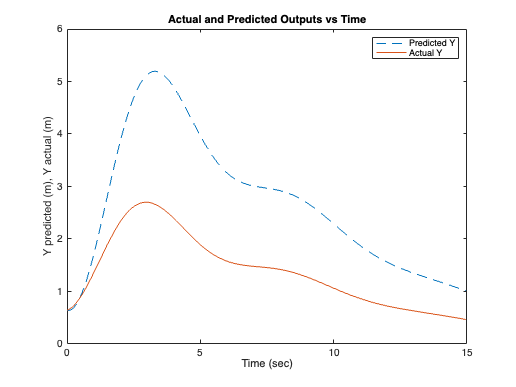



%
% find initial conditions
% we know that y(1) = Hx(1)
% so x(1) = pinv(H)*y(1)
x1 = pinv(H)*ydata(1);
u1 = -gains*x1;              % input at x1

% x(1) = Fx(0) + Gu so x(0) = F^1(x(1)-Gu)
x0 = inv(F)*(x1-G*u1);

y_1 =  x1(1) - l*sin(x1(3)); % y1 = z - lsin(theta)'
u = -gains*[x0, x1] ;
xdot = [x0,x1];             % assign first xdot
ypred = y_1;                % assign first y prediction

for i=2:n
    u(i) = -gains*xdot(1:4,i-1); % calculate input at each step
    xdot(:,i) = F*xdot(:,i-1) + G*u(i)';
    ypred(:,i) = H*xdot(:,i);
end

f3=figure;
plot(tlist(1:300),ypred,"--",tlist(1:300),ydata')
title('Actual and Predicted Outputs vs Time')
xlabel('Time (sec)')
ylabel('Y predicted (m), Y actual (m)')
legend({'Predicted Y', 'Actual Y'},'Location','northeast')

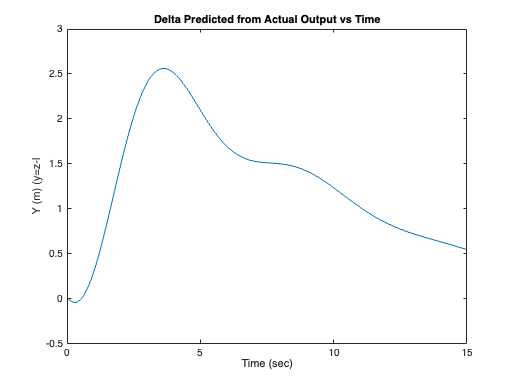


f2=figure;
plot(tlist(2:301),ypred-ydata')
title('Delta Predicted from Actual Output vs Time')
xlabel('Time (sec)')
ylabel('Y (m) (y=z-l')

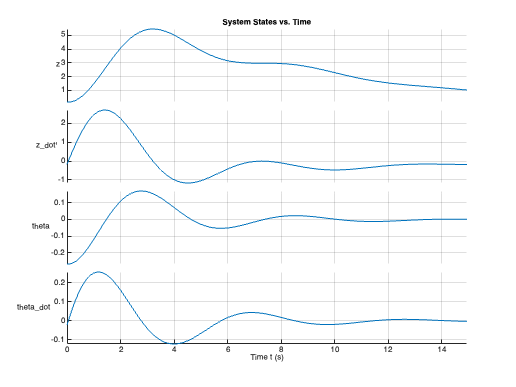


f1=figure;
s=stackedplot(tlist(1:n), xdot');
xlabel('Time t (s)');
s.DisplayLabels={'z', 'z_dot''', 'theta', 'theta_dot'};
ax = findobj(s.NodeChildren, 'Type','Axes');
set([ax.YLabel],'Rotation',90,'HorizontalAlignment', 'Center', 'VerticalAlignment', 'Bottom')
title('System States vs. Time');
grid on;



%  corrected x0 answer %
Fmod = F-(G*gains) ; % since both gain and F are multiplied to x, make modified matrix

Fmod =     1.0000    0.0501   -0.0160   -0.0032
    0.0007    1.0059   -0.6417   -0.1252
    0.0000    0.0001    0.9980    0.0484
    0.0004    0.0032   -0.0819    0.9388


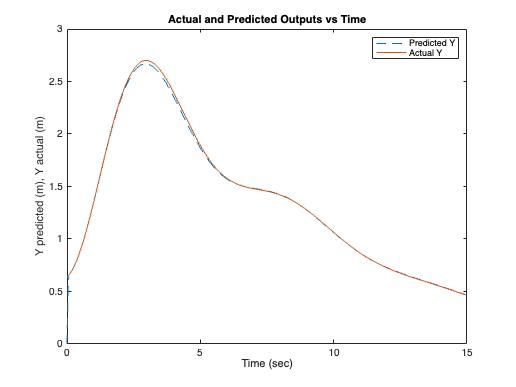

xmod = inv([H;H*Fmod;H*Fmod^2;H*Fmod^3])*ydata(1:4); % x0 = inv(O)*y

for i=2:n
    xmod(:,i) = Fmod*xmod(:,i-1) ;
    ymod(:,i) = H*xmod(:,i);
end

f4=figure;
plot(tlist(1:300),ymod,"--",tlist(1:300),ydata')
title('Actual and Predicted Outputs vs Time')
xlabel('Time (sec)')
ylabel('Y predicted (m), Y actual (m)')
legend({'Predicted Y', 'Actual Y'},'Location','northeast')


%     l = 1.85;           % length of rod
%     m = 2;              % point mass
%     M = 4;         
%     dy = zeros(4,1);
%     dy(1) = y(2);
%     dy(2) = (m*9.81*sin(y(3))*cos(y(3))-m*l*y(4)^2*sin(y(3)))/(M+m*sin(y(3))^2);
%     dy(3) = y(3);
%     dy(4) = ( 9.81*sin(y(3))*cos(y(3))^2 - m*l*y(4)^2*sin(y(3))*cos(y(3)) + 9.81 * sin(y(3))*(M+m*sin(y(3))^2))/(l*(M+m*sin(y(3))^2));
% 
% end
% 